data = readtable('Ti64Al12.xlsx');
data.Properties.VariableNames = {'Strain','Strain Rate','T1','T2','T3','T4','T5','T6'}

data = 31x8 table
    Strain    Strain Rate     T1       T2       T3       T4       T5       T6  
    ______    ___________    _____    _____    _____    _____    _____    _____

     NaN           NaN         750      800      850      900      950     1000
     0.1         0.001       218.5    145.5     94.8     60.4     22.8       12
     0.1          0.01       326.1    238.5    184.6    118.4     63.3     23.2
     0.1           0.1       422.7    375.8    262.8    180.2     99.2     44.1
     0.1             1       541.9    419.1    367.8    251.6      164     74.5
     0.1            10       548.3    542.8      424    342.4    214.3    122.2
     0.1           100       677.2    573.2    489.2    385.8    259.

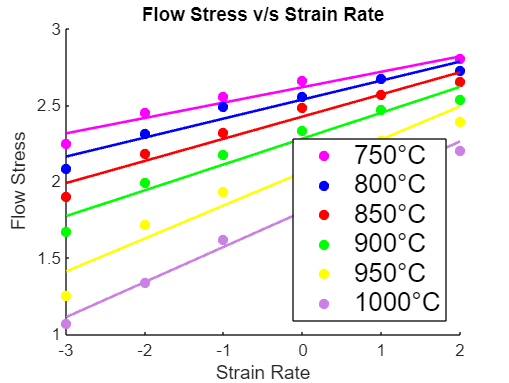

data(1,:)=[];


datan= table2array(data);
% 0.1 strain
strain_1 = datan(13:18,2:end);
sr1 = strain_1(:,1);
strainlog = log10(sr1);
stress1 = strain_1(:,2:end);y = zeros(6,6);
stresslog = log10(stress1);
C = {'m','b','r','g','y',[.8 .5 .9]};
hold on
for r = 1:length(stress1)
    Scatter(r) =scatter(strainlog,stresslog(:,r),'filled','MarkerFaceColor',C{r});
    c= polyfit(log10(sr1),log10(stress1(:,r)),1);
    y(:,r) = polyval(c,log10(sr1));
    plot(log10(sr1),y(:,r),'LineWidth',1.5,'Color',C{r})
end
ylabel('Flow Stress');xlabel('Strain Rate');
title('Flow Stress v/s Strain Rate')
legend(Scatter,'750°C','800°C','850°C','900°C','950°C','1000°C','Location','southeast','FontSize',15);
hold off

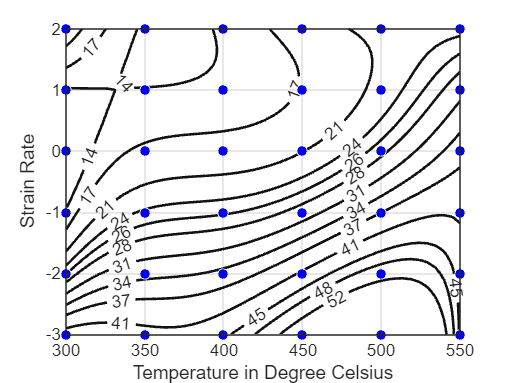



%slope or strain rate sensitivity
%slope or strain rate sensitivity
m= zeros(length(stress1),length(stress1));
for k =  1:length(stress1)
    for p = 1:length(stress1)
        c1= polyfit(log10(sr1),log10(stress1(:,k)),3);
        deriv = polyder(c1);
        m(p,k) = polyval(deriv,strainlog(p));
    end
end


e= (2*m./(m+1))*100;
T= 300:50:550;
%instability zone
e1= e/200;
slope= zeros(length(stress1),length(stress1));
for k =  1:length(stress1)
    for p =  1:length(stress1)
        c2= polyfit(log10(sr1),log10(e1(:,k)),3);
        deriv = polyder(c2);
        slope(p,k) = polyval(deriv,strainlog(p));
        
    end
end
iz = slope +m;



[xData, yData, zData] = prepareSurfaceData( T, strainlog, e );

% Set up fittype and options.
ft = fittype( 'poly45' );

% Fit model to data.
[fitresult, gof] = fit( [xData, yData], zData, ft, 'Normalize', 'on' );

% Make contour plot.
figure( 'Name', 'Power Dissipation' );
h = plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );
% Label axes
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );
ylabel( 'Strain Rate', 'Interpreter', 'none' );

grid on
set(h(1),'ShowText','on','LabelSpacing',144)
set(h(1),'LineWidth',1.5,'Fill','off');
set(h(1),'LevelList',[3,7,10,14,17,21,24,26,28,31,34,37,41,45,48,52])
fig = gcf;
saveas(gcf,'pd0_5.jpg')

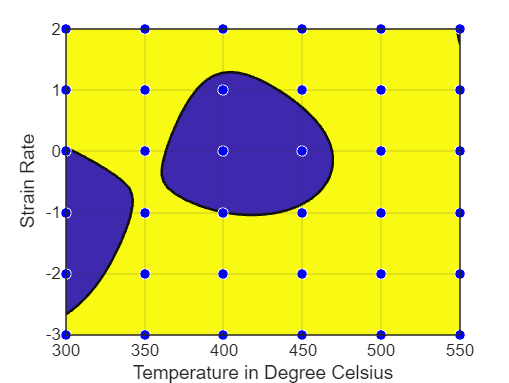



[xData, yData, zData] = prepareSurfaceData( T, strainlog, iz );

% Set up fittype and options.
ft = fittype( 'poly45' );

% Fit model to data.
[fitresult, gof] = fit( [xData, yData], zData, ft, 'Normalize', 'on' );

% Make contour plot.
figure( 'Name', 'untitled fit 2' );
w=plot( fitresult, [xData, yData], zData, 'Style', 'Contour' );
% Label axes
xlabel( 'Temperature in Degree Celsius', 'Interpreter', 'none' );
ylabel( 'Strain Rate', 'Interpreter', 'none' );
grid on
set(w(1),'LineWidth',1.5);
set(w(1),'LineWidth',1.5,'LevelStep',2);
fig = gcf;
saveas(gcf,'is0_5.jpg')

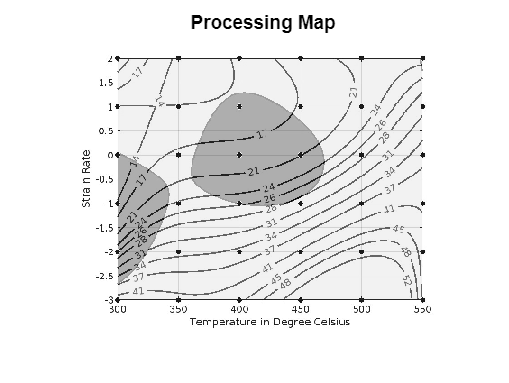



% BASIC IMAGE PROCESSING : SUPERIMPOSE
fig1 = imread('pd0_5.jpg');
fig2 = imread('is0_5.jpg');
fusionimage=imfuse(fig1,fig2,'falsecolor','Scaling','joint');
op=rgb2gray(fusionimage);
imshow(op);
title('Processing Map')